# Example: MHKiT-MATLAB Power Module 

This example will demonstrate the MHKiT Power Module functionality to compute power, fundamental frequency, harmonics, and flickers from time series of voltage and current.

## Load Power Data

We will begin by reading in timeseries data of measured three phase (a,b,and,c) voltage and current. The IEC TS 62600-30 requires that you perform power quality assessments on a minimum of 10-min timseries data, but for this example we will only look at a fraction of that.

% Read in timeseries data of voltage (V) and current (I)
power_table = readtable('../examples/data/power/2020224_181521_PowRaw.csv');
power_table

power_table = 8000×7 table
           Time_UTC            MODAQ_Va_V    MODAQ_Vb_V    MODAQ_Vc_V    MODAQ_Ia_I    MODAQ_Ib_I    MODAQ_Ic_I
    _______________________    __________    __________    __________    __________    __________    __________

    2020-02-24 18:15:21.499      10653        -8499.4       -1850.2       -23.214         19.22        4.0234  
    2020-02-24 18:15:21.500      10691        -8428.7       -1927.6       -23.405        19.182        4.2899  
    2020-02-24 18:15:21.500      10733          -8365       -2001.3       -23.493        19.034        4.4789  
    2020-02-24 18:15:21.500      10776        -8304.6       -2071.2        -23.68        18.918        4.8582  
    2020-02-24 18:15:21.500      10818        -8248.1         

To use the MHKiT-MATLAB power module we need to create structures of current and voltage. 

current.time = posixtime(power_table.Time_UTC); %setting time in current structure 
voltage.time = posixtime(power_table.Time_UTC); %setting time in voltage structure
T2 = mergevars(power_table,[2 3 4]); %combining the voltage time series into one table variable
T3 = mergevars(T2,[3 4 5]); %combining the current time series into one table variable
current.current = T3.Var3;
voltage.voltage = T3.Var2;

## Power Characteristics 

The MHKiT `power characteristics` submodule can be used to compute basic quantities of interest from voltage and current time series. In this example we will calculate active AC power and fundamental frequency, using the loaded voltage and current timeseries.

To compute the active AC power, we will need the power factor. Power factor describes the efficency of the energy device.

% Set the power factor for the system
power_factor = 0.96 

power_factor = 0.9600

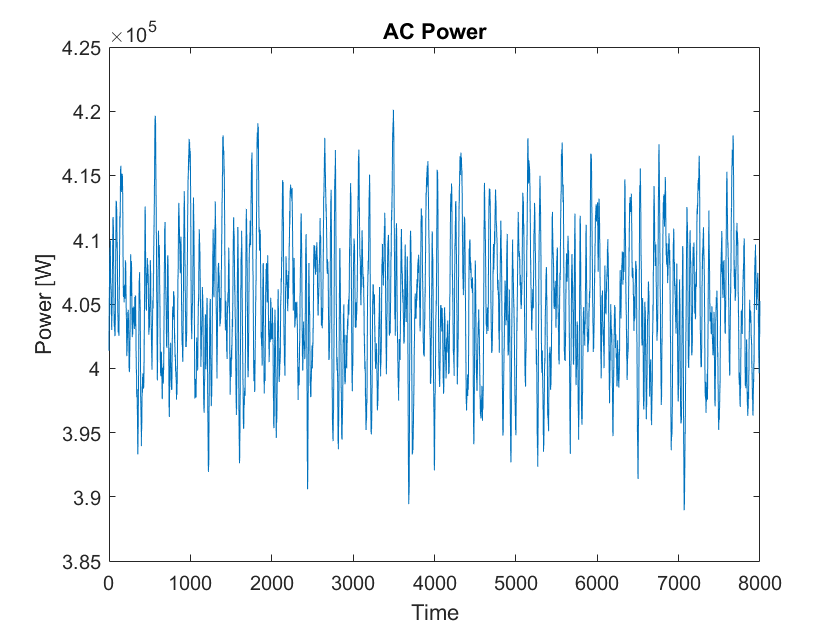

% Compute the instantaneous AC power in watts
ac_power = ac_power_three_phase(voltage, current, power_factor); 
% Display the result
plot(ac_power.time,ac_power.power);
title('AC Power')
ylabel('Power [W]')
xlabel('Time')

### Fundamental Frequency

Using the 3 phase voltage measurements we can compute the fundamental frequency of the voltage timeseries. The time-varying fundamental frequency is a required metric for power quality assessments. The function `calc_fundamental_freq() `provides two options of calculating the fundamental frequency: 1. Short-Time Fourier Transform (STFT); 2. Zero-Crossing Detction (ZCD). Here we illustrate the steps in both ways.

First, let's look at the STFT method. Note that, to obtain an accurate result, window settings for STFT is crucial, the user might need some exploratory analysis and try different sets of parameters.

%Hilbert method: instantaneous_frequency
%inst_freq = instantaneous_frequency(voltage)

%STFT method:
% set up method options:
methodopts = {'Window',rectwin(5000),'OverlapLength',3750,...
    'FFTLength',50e3,'FrequencyRange','onesided'};
% prep input and output
u_m = struct();u_m.time = voltage.time; 
fund_freq= struct();fund_freq.time = voltage.time;
fund_freq.data=zeros(size(voltage.voltage));
for i=1:3
    u_m.data=voltage.voltage(:,i);
    [~,freq] = calc_fundamental_freq(u_m,'stft',methodopts);
    fund_freq.data(:,i) = freq.data;
end
fund_freq

fund_freq = struct with fields:
    time: [8000×1 double]
    data: [8000×3 double]


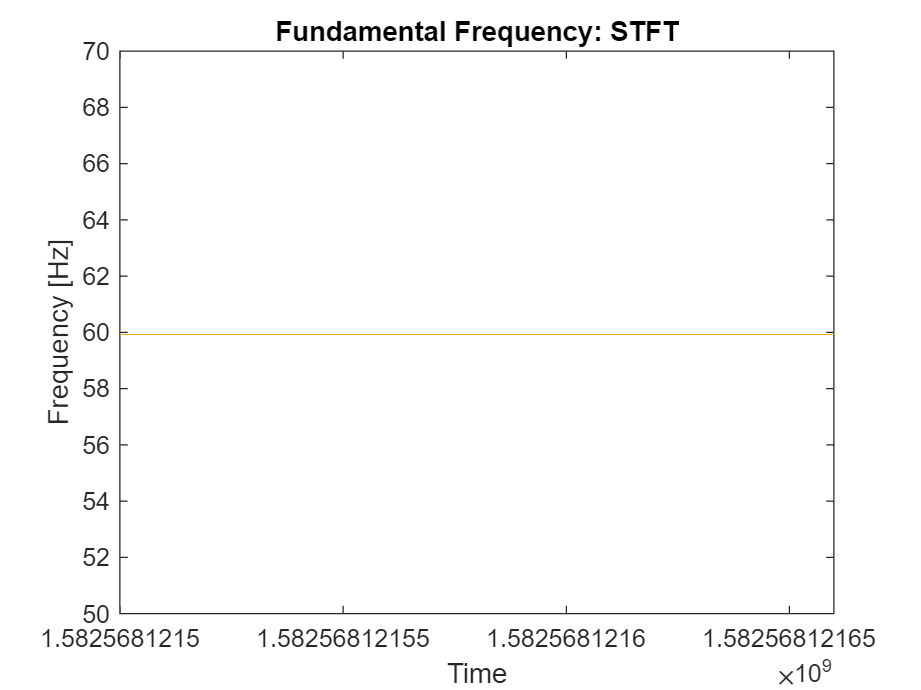

%Display the result
hold off; plot(fund_freq.time,fund_freq.data);
title('Fundamental Frequency: STFT')
ylabel('Frequency [Hz]')
xlabel('Time')
ylim([50,70])

Now, let's look at the ZCD method. Note that, ZCD method may not work for conditions of distorted voltage with multiple zero-crossings, like the one stated in IEC TS 61400-21-1 B.3.3. As stated above, exploratory analysis is needed.

%ZCD method:
% prep input and output
u_m = struct();u_m.time = voltage.time; 
fund_freq= struct();fund_freq.time = voltage.time;
fund_freq.data=zeros(size(voltage.voltage));
% for the zcd method, we don't need to worry about the 
% method options. 
methodopts = {};
for i=1:3
    u_m.data=voltage.voltage(:,i);
    [~,freq] = calc_fundamental_freq(u_m,'zcd',methodopts);
    fund_freq.data(:,i) = freq.data;
end
fund_freq

fund_freq = struct with fields:
    time: [8000×1 double]
    data: [8000×3 double]


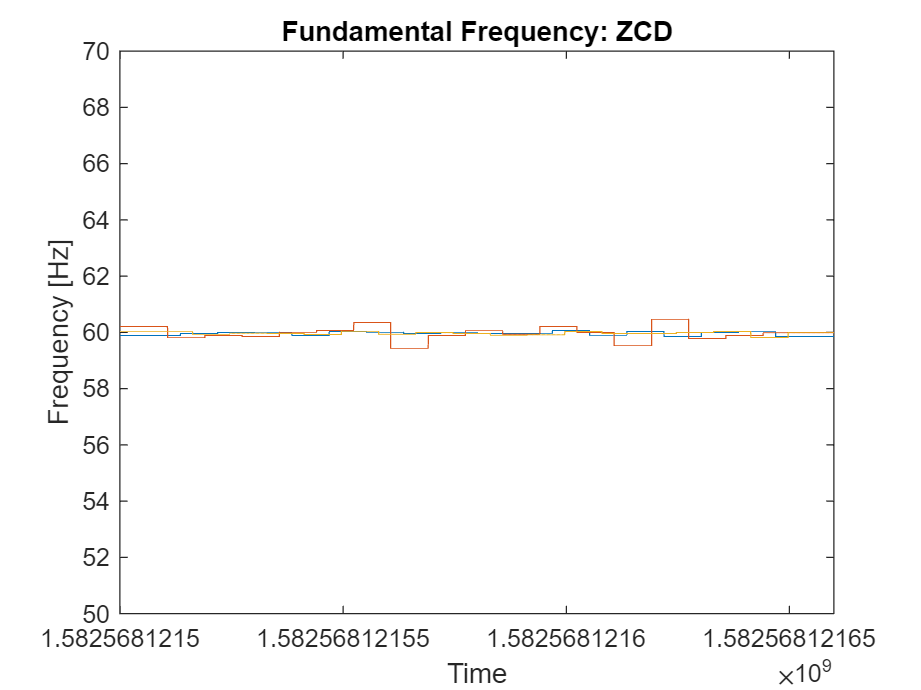

hold off;plot(fund_freq.time,fund_freq.data);
title('Fundamental Frequency: ZCD')
ylabel('Frequency [Hz]')
xlabel('Time')
ylim([50,70])

## Power Quality

The power quality submodule can be used to compute voltage fluctuations, harmonics of current and voltage and current distortions following IEC TS 62600-30 and IEC 61000-4-7. Harmonics and harmonic distortion are required as part of a power quality assessment and characterize the stability of the power being produced. Specifically, we focus on the flicker coefficient for continuous operation (MV connected systems), which is a normalised measure of the flicker emission during continuous operation of the MEC unit.

% Set the sampling frequency of the dataset 
sample_freq = 50000   %[Hz]

sample_freq = 50000

% Set the frequency of the grid the device would be conected to
grid_freq = 60        %[Hz] 

grid_freq = 60

% Set the rated current of the device
rated_current = 18.8  % [Amps]

rated_current = 18.8000


% Calculate the current harmonics
h = harmonics(current, sample_freq, grid_freq);

Error using <a href="matlab:matlab.internal.language.introspective.errorDocCallback('contours><module>')" style="font-weight:bold">contours><module></a>
Python Error: ModuleNotFoundError: No module named 'statsmodels'

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('__init__><module>', 'c:\users\kchong\mhkit-python\mhkit\wave\__init__.py', 5)" style="font-weight:bold">__init__><module></a> (line 5)

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('__init__><module>', 'c:\users\kchong\mhkit-python\mhkit\__init__.py', 1)" style="font-weight:bold">__init__><module></a> (line 1)

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('<frozen importlib>_call_with_frames_removed', '<frozen importlib._bootstrap>', 241)" styl

% display the results 
plot(h.harmonic,h.amplitude);
title('Current Harmonics')
xlabel('Frequency [Hz]')
ylabel('Harmonic Amplitude')
xlim([0,900])

### Harmonic Subgroups

The harmonic subgroups calculations are based on IEC TS 62600-30. We can clculate them using our grid frequency and harmonics.

% Calcualte Harmonic Subgroups
h_s = harmonic_subgroups(h,grid_freq) 

h_s = struct with fields:
    amplitude: [51×3 double]
     harmonic: [0 60 120 180 240 300 360 420 480 540 600 660 720 780 840 900 960 1020 1080 1140 1200 1260 1320 1380 1440 1500 1560 1620 1680 1740 1800 1860 1920 1980 2040 2100 2160 2220 2280 2340 2400 2460 2520 2580 2640 2700 2760 2820 2880 2940 3000]


### Total Harmonic Current Distortion 

Compute the THCD from harmonic subgroups and rated current for the device

% Finally we can compute the total harmonic current distortion as a percentage
% for each channel
THCD = total_harmonic_current_distortion(h_s,rated_current) 

THCD =     8.9725    6.0966    5.9295


### **Flicker Assessment**

Calculate the flicker coefficient following the steps in IEC TS 62600-30 section 7.2.1: MV connected marine energy converters. 

#### 1. Calculate the simulated voltage of the fictitious grid (u_fic).

There are two options for calculation of u_fic. 

First, the user can use `flicker_ufic_workflow()`, which wrapped up all steps needed to the calculation of u_fic from measured voltage (u_m) and current (i_m). All intermediate values can also be outputted for the user to debug. 

Or, the user can call the corresponding functions sequentially. For illustration purpose, we show both ways. 

**Firstly,** let's use `flicker_ufic_workflow()`. 

% prep the input: look at the first phase for an example
u_m = struct();u_m.time = voltage.time; 
u_m.data=voltage.voltage(:,1);
i_m = struct();i_m.time = current.time; 
i_m.data = current.current(:,1);
Sr = 4.2e5; % rated power
Un = 14e3; % RMS value of the nominal voltage
SCR = 20;% short-circuit ratio
fg = 60; % nominal grid frequency
% method settings for calculation of fundamental frequency 
% of u_m, see above
method = 'zcd'; methodopts = {};
out = flicker_ufic_workflow(Sr,Un,SCR,fg, ...
        u_m,i_m,method,methodopts);
u0=out.u0;
out

out = struct with fields:
       time: [8000×1 double]
       Rfic: [20.2073 14.9984 7.9805 2.0336]
       Lfic: [0.0309 0.0474 0.0582 0.0617]
     alpha0: 1.1961
       freq: [1×1 struct]
    alpha_m: [8000×1 double]
         u0: [8000×1 double]
      u_fic: [8000×4 double]


Calculating u_fic can be tricky due to the part of calculating the ideal voltage source (u0), as mentioned in the IECTS 62600-30, u0 should fullfill the following two requirements:

(1) be without any fluctuations; (2) have the same electrical angle as the fundamental of u_m.

Therefore, here we compare u0 and u_m to check if our output fullfills these requirements.

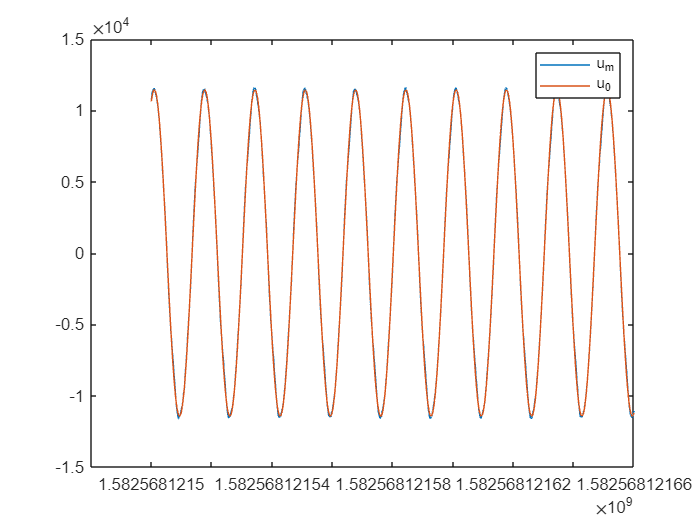

% check u0
hold off;plot(u_m.time,u_m.data);hold on; 
plot(u_m.time,u0);legend('u_m','u_0');

**Secondly,** we can also calculate u_fic step by step. The calculation of u_fic can be achieved sequentially in 5 steps:

- Step 1. Construct the fictitious grid: calculate resistance and inductance using `calc_Rfic_Lfic().`

[Rfic,Lfic] = calc_Rfic_Lfic(Sr, SCR, Un, fg);

- Step 2. Calculate the fundamental frequency and the initial electrical angle (alpha_0) of u_m using `calc_fundamental_freq(). `

            As already meantioned above, we have two options, since ZCD is used above, here we test out the STFT method.

% step 2. Calculate the fundamental frequency and alpha_0:
%   -opt1: method ZCD: method = 'ZCD'; methodopts={};
%   -opt2: method STFT: method = 'stft'; methodopts = {'Window',rectwin(M),...
%           'OverlapLength',L,'FFTLength',128,'FrequencyRange','onesided'};
method = 'stft'; methodopts = {'Window',rectwin(5000),'OverlapLength',3750,...
    'FFTLength',50e3,'FrequencyRange','onesided'};
[alpha0,freq] = calc_fundamental_freq(u_m,method,methodopts);

- Step 3. Calculate the electrical angle (alpha_m) of the fundamental of u_m using `calc_electrical_angle()`.

alpha_m = calc_electrical_angle(freq,alpha0);

- Step 4. Calculate u0 from alpha_m and nominal voltage (Un) using `calc_ideal_voltage()`.

u0 = calc_ideal_voltage(Un,alpha_m);

- Step 5. Calculate u_fic using `calc_simulated_voltage()`.

u_fic = calc_simulated_voltage(u0,i_m,Rfic,Lfic);
disp(size(u_fic));

        8000           4



Again, we check our derived u0 to see if it fullfills the requirements.

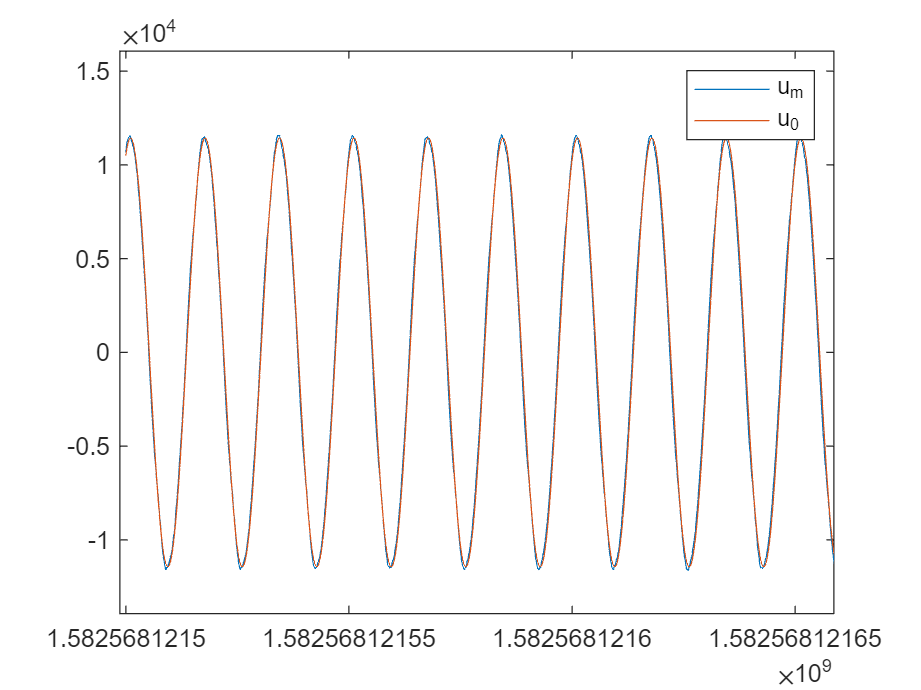

% check u0
hold off;plot(u_m.time,u_m.data);hold on; 
plot(u_m.time,u0);legend('u_m','u_0');

#### 2. Calculate the flicker emission value (P_stfic) from u_fic.

Input u_fic into an appropriate digital flickermeter to get the P_stfic. 

According to the standard, the evaluation time is 10 min, therefore, to fullfill this requirement, we need data length >= 10min. And note that we may need to discard the first 20s depending on the performace of the flickermeter we choose.

% prep input for the digital flickermeter
time = u_m.time-u_m.time(1);
u_fic_in = timeseries(u_fic(:,2),time);
u_fic_in

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [8000x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [8000x1 double]
        DataInfo: 

A digital flickermeter that also contains an interface of statistical analysis in simulink can be used to generate the instantaneous flicker level (`out.S5`) and then calculate the Pst using the statistical tool associated with it. More details can be found [here](https://www.mathworks.com/help/sps/powersys/ref/digitalflickermeter.html). 

Note that the user needs to specify RMS value for voltage, sampling frequencies, and other parameters to achieve a valid result. In addition, there may be some unrealiable peaks in the instantaneous flicker levels derived from this particular flickermeter, when performing statistical analysis, be sure to discard the S5 data at the very beginning of it. 

% prep input for the statistical tool
% out.S5 is the result generated from the digital flickermeter.
S5 = out.S5;

After getting the instantaneous flicker levels, double-click the digital flickermeter to open statistical tools to calculate P_stfic.

#### 3. Calculate the flicker coefficient.

% Provide a flickermeter output (P_stfic).
% In this example, data duration is < 1s, 
% so we fake a number here for P_stfic
P_stfic = 0.10016; 
Xfic = 2*pi*fg*Lfic;
S_kfic = (Un^2)./sqrt(Rfic.^2+Xfic.^2);
coef_flicker=calc_flicker_coefficient(P_stfic,S_kfic(1),Sr);
coef_flicker

coef_flicker = 2.0032

#### 4. Test the performace of the flicker assessment process

This part of the example illustrates how to test the performance of the user's flicker assessment process, including methods to generate simulated voltage of the fictitious grid and the performance of the (digital) flickermeter, following the guidance provided in the IECTS 61400-21-1 Annex B.3: Verification test of the measurement procedure for flicker.

The verification is straightforward, we generate testing data with predetermined flicker coefficients and verify the flicker assessment process by comparing the derived flicker coefficient with the predetermined ones. The testing data generated wiill be measured voltage and current time series (`u_m` and `i_m`), and the user can use `gen_test_data()` to generate test data for five different scenarios: (1) pure sine wave (coef=0) and scenarios (2)-(5) as stated Annex B.3.2 - B.3.5, and test them one by one. Here we illustrate the usage of gen_test_data by generating distorted u_m(t) with multiple zero crossings (see Annex B.3.3 for details).

% set up proper input parameters:
% scenario 3 with duration of 10s
opt = 3; T=10;
% rated parameters:
Un=12e3; In=144; fs=50e3; Sr = 3e6;
% other parameters for generating distorted data
fg=60;  SCR=20; fm=25; 
fv=0.5; % fv only needed for scenario B.3.4
% According to IECTS 61400-21-1 Table B.2: 
DeltaI_I = [4.763 5.726 7.640 9.488]; 
[i_m,u_m]=gen_test_data(Un,In,fg,fs,fm,fv,DeltaI_I,opt,T)

i_m = struct with fields:
    time: [500000×1 double]
    data: [500000×4 double]


u_m = struct with fields:
    time: [500000×1 double]
    data: [500000×1 double]


The generated i_m(ntime, nphi_k) has 4 time serieses, corresponding to phi_k = 30, 50, 70, 85. While u_m is always the same, thus has only one time series.

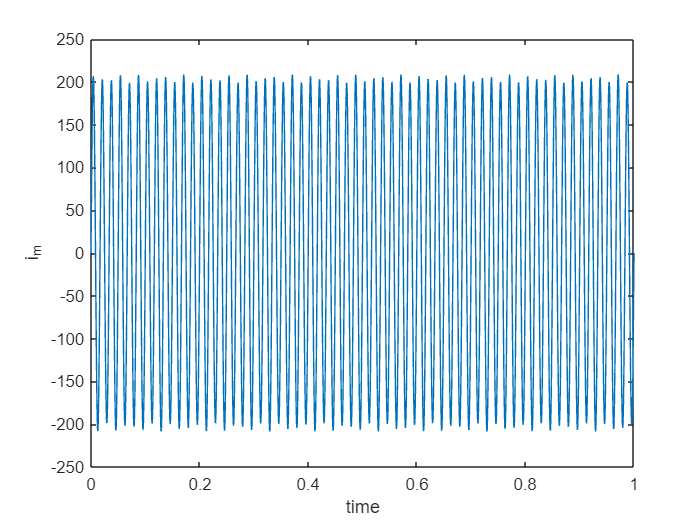

hold off; plot(i_m.time,i_m.data(:,1));xlim([0 1]);xlabel("time");ylabel("i_m")

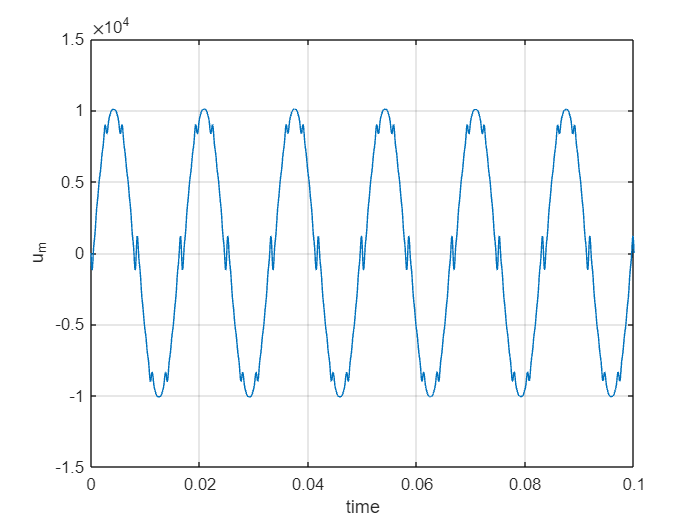

plot(u_m.time,u_m.data);xlim([0 0.1]);xlabel("time");ylabel("u_m");grid on;